# A Estimation curve VS different S_EI:L6 added

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\GitHub\NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

load('NtWk_Archit.mat')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.5;  
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Network Simulation

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

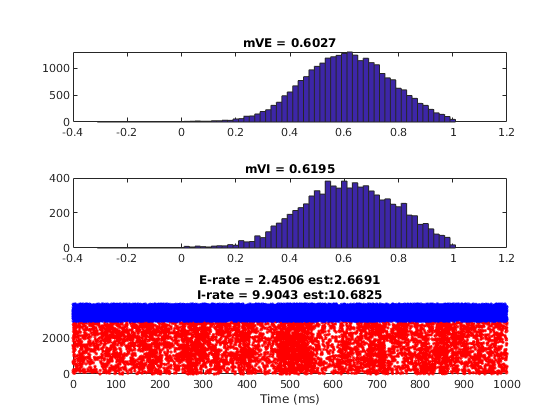

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

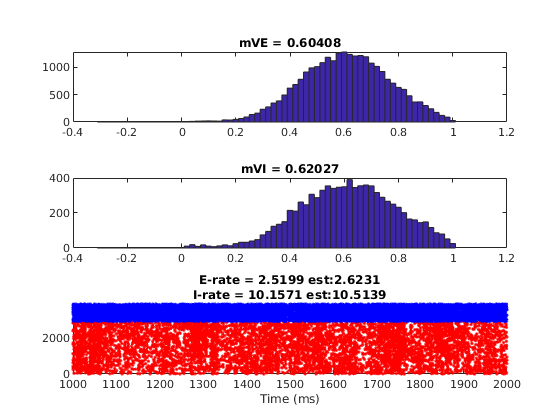

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.3; N_EEDly = floor(T_EEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 20;
Sliding = 5;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);

%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE,C_EI,C_IE,C_II,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        h = figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

toc

Elapsed time is 95.175897 seconds.



NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop



## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X));
OD_EMap = zeros(n_E_HC*N_HC);
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X));
OD_IMap = zeros(n_I_HC*N_HC);
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN input classified by domains

DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
DriveI = 48*4/1e3;
lambda_E_drive = DriveE(OD_E)';
lambda_I_drive = DriveI;

Simulation

Then make a transfer between neurons in HCs and 10*10 pixels

SampleInd = 2

ans = 0.0591

SampleInd = 3

ans = 0.0788

SampleInd = 4

ans = 0.1001

SampleInd = 5

ans = 0.1238

SampleInd = 6

ans = 0.1462

SampleInd = 7

ans = 0.1685

SampleInd = 8

ans = 0.1856

SampleInd = 9

ans = 0.1962

SampleInd = 10

ans = 0.1991

SampleInd = 11

ans = 0.1946

SampleInd = 12

ans = 0.1815

SampleInd = 13

ans = 0.1630

SampleInd = 14

ans = 0.1335

SampleInd = 15

ans = 0.0914

SampleInd = 16

ans = 0.0516

SampleInd = 17

ans = 0.0179

SampleInd = 18

ans = 0.0058

SampleInd = 19

ans = 0.0030

SampleInd = 20

ans = 0.0027

SampleInd = 21

ans = 0.0025

SampleInd = 22

ans = 0.0024

SampleInd = 23

ans = 0.0028

SampleInd = 24

ans = 0.0027

SampleInd = 25

ans = 0.0025

SampleInd = 26

ans = 0.0029

SampleInd = 27

ans = 0.0036

SampleInd = 28

ans = 0.0040

SampleInd = 29

ans = 0.0046

SampleInd = 30

ans = 0.0057

SampleInd = 31

ans = 0.0060

SampleInd = 32

ans = 0.0068

SampleInd = 33

ans = 0.0077

SampleInd = 34

ans = 0.0083

SampleInd = 35

ans = 0.0085

SampleInd = 36

ans = 0.0098

SampleInd = 37

ans = 0.0098

SampleInd = 38

ans = 0.0115

SampleInd = 39

ans = 0.0126

SampleInd = 40

ans = 0.0136

SampleInd = 41

ans = 0.0154

SampleInd = 42

ans = 0.0188

SampleInd = 43

ans = 0.0198

SampleInd = 44

ans = 0.0232

SampleInd = 45

ans = 0.0265

SampleInd = 46

ans = 0.0297

SampleInd = 47

ans = 0.0307

SampleInd = 48

ans = 0.0314

SampleInd = 49

ans = 0.0334

SampleInd = 50

ans = 0.0380

SampleInd = 51

ans = 0.0388

SampleInd = 52

ans = 0.0395

SampleInd = 53

ans = 0.0426

SampleInd = 54

ans = 0.0448

SampleInd = 55

ans = 0.0448

SampleInd = 56

ans = 0.0451

SampleInd = 57

ans = 0.0469

SampleInd = 58

ans = 0.0461

SampleInd = 59

ans = 0.0435

SampleInd = 60

ans = 0.0426

SampleInd = 61

ans = 0.0398

SampleInd = 62

ans = 0.0379

SampleInd = 63

ans = 0.0327

SampleInd = 64

ans = 0.0295

SampleInd = 65

ans = 0.0272

SampleInd = 66

ans = 0.0232

SampleInd = 67

ans = 0.0221

SampleInd = 68

ans = 0.0189

SampleInd = 69

ans = 0.0200

SampleInd = 70

ans = 0.0184

SampleInd = 71

ans = 0.0190

SampleInd = 72

ans = 0.0188

SampleInd = 73

ans = 0.0190

SampleInd = 74

ans = 0.0190

SampleInd = 75

ans = 0.0200

SampleInd = 76

ans = 0.0197

SampleInd = 77

ans = 0.0204

SampleInd = 78

ans = 0.0202

SampleInd = 79

ans = 0.0237

SampleInd = 80

ans = 0.0238

SampleInd = 81

ans = 0.0261

SampleInd = 82

ans = 0.0277

SampleInd = 83

ans = 0.0293

SampleInd = 84

ans = 0.0319

SampleInd = 85

ans = 0.0341

SampleInd = 86

ans = 0.0337

SampleInd = 87

ans = 0.0361

SampleInd = 88

ans = 0.0356

SampleInd = 89

ans = 0.0336

SampleInd = 90

ans = 0.0383

SampleInd = 91

ans = 0.0367

SampleInd = 92

ans = 0.0388

SampleInd = 93

ans = 0.0375

SampleInd = 94

ans = 0.0375

SampleInd = 95

ans = 0.0391

SampleInd = 96

ans = 0.0377

SampleInd = 97

ans = 0.0354

SampleInd = 98

ans = 0.0344

SampleInd = 99

ans = 0.0325

SampleInd = 100

ans = 0.0321

SampleInd = 101

ans = 0.0288

SampleInd = 102

ans = 0.0274

SampleInd = 103

ans = 0.0258

SampleInd = 104

ans = 0.0253

SampleInd = 105

ans = 0.0219

SampleInd = 106

ans = 0.0226

SampleInd = 107

ans = 0.0224

SampleInd = 108

ans = 0.0220

SampleInd = 109

ans = 0.0211

SampleInd = 110

ans = 0.0211

SampleInd = 111

ans = 0.0216

SampleInd = 112

ans = 0.0227

SampleInd = 113

ans = 0.0218

SampleInd = 114

ans = 0.0250

SampleInd = 115

ans = 0.0259

SampleInd = 116

ans = 0.0282

SampleInd = 117

ans = 0.0294

SampleInd = 118

ans = 0.0336

SampleInd = 119

ans = 0.0338

SampleInd = 120

ans = 0.0355

SampleInd = 121

ans = 0.0356

SampleInd = 122

ans = 0.0362

SampleInd = 123

ans = 0.0370

SampleInd = 124

ans = 0.0359

SampleInd = 125

ans = 0.0366

SampleInd = 126

ans = 0.0360

SampleInd = 127

ans = 0.0320

SampleInd = 128

ans = 0.0333

SampleInd = 129

ans = 0.0323

SampleInd = 130

ans = 0.0293

SampleInd = 131

ans = 0.0291

SampleInd = 132

ans = 0.0282

SampleInd = 133

ans = 0.0273

SampleInd = 134

ans = 0.0263

SampleInd = 135

ans = 0.0246

SampleInd = 136

ans = 0.0246

SampleInd = 137

ans = 0.0228

SampleInd = 138

ans = 0.0227

SampleInd = 139

ans = 0.0218

SampleInd = 140

ans = 0.0197

SampleInd = 141

ans = 0.0207

SampleInd = 142

ans = 0.0226

SampleInd = 143

ans = 0.0247

SampleInd = 144

ans = 0.0227

SampleInd = 145

ans = 0.0249

SampleInd = 146

ans = 0.0283

SampleInd = 147

ans = 0.0300

SampleInd = 148

ans = 0.0305

SampleInd = 149

ans = 0.0295

SampleInd = 150

ans = 0.0316

SampleInd = 151

ans = 0.0339

SampleInd = 152

ans = 0.0362

SampleInd = 153

ans = 0.0377

SampleInd = 154

ans = 0.0384

SampleInd = 155

ans = 0.0374

SampleInd = 156

ans = 0.0382

SampleInd = 157

ans = 0.0376

SampleInd = 158

ans = 0.0361

SampleInd = 159

ans = 0.0372

SampleInd = 160

ans = 0.0338

SampleInd = 161

ans = 0.0341

SampleInd = 162

ans = 0.0327

SampleInd = 163

ans = 0.0318

SampleInd = 164

ans = 0.0299

SampleInd = 165

ans = 0.0268

SampleInd = 166

ans = 0.0276

SampleInd = 167

ans = 0.0236

SampleInd = 168

ans = 0.0206

SampleInd = 169

ans = 0.0213

SampleInd = 170

ans = 0.0204

SampleInd = 171

ans = 0.0206

SampleInd = 172

ans = 0.0215

SampleInd = 173

ans = 0.0211

SampleInd = 174

ans = 0.0208

SampleInd = 175

ans = 0.0211

SampleInd = 176

ans = 0.0245

SampleInd = 177

ans = 0.0243

SampleInd = 178

ans = 0.0249

SampleInd = 179

ans = 0.0285

SampleInd = 180

ans = 0.0284

SampleInd = 181

ans = 0.0297

SampleInd = 182

ans = 0.0315

SampleInd = 183

ans = 0.0327

SampleInd = 184

ans = 0.0340

SampleInd = 185

ans = 0.0406

SampleInd = 186

ans = 0.0411

SampleInd = 187

ans = 0.0418

SampleInd = 188

ans = 0.0433

SampleInd = 189

ans = 0.0461

SampleInd = 190

ans = 0.0415

SampleInd = 191

ans = 0.0461

SampleInd = 192

ans = 0.0399

SampleInd = 193

ans = 0.0376

SampleInd = 194

ans = 0.0354

SampleInd = 195

ans = 0.0322

SampleInd = 196

ans = 0.0286

SampleInd = 197

ans = 0.0262

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.21415, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

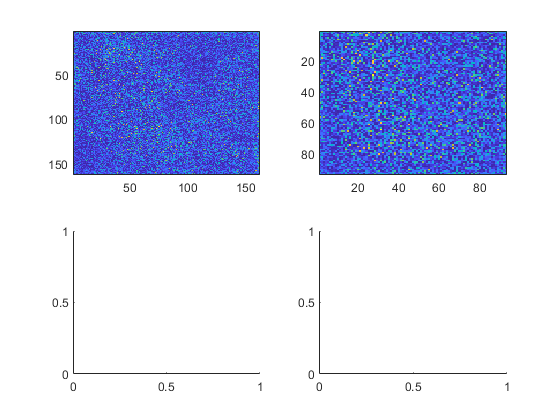

历时 99.806116 秒。


SampleInd = 198

ans = 0.0248

SampleInd = 199

ans = 0.0235

SampleInd = 200

ans = 0.0221

SampleInd = 201

ans = 0.0203

SampleInd = 202

ans = 0.0165

SampleInd = 203

ans = 0.0162

SampleInd = 204

ans = 0.0174

SampleInd = 205

ans = 0.0178

SampleInd = 206

ans = 0.0181

SampleInd = 207

ans = 0.0184

SampleInd = 208

ans = 0.0192

SampleInd = 209

ans = 0.0219

SampleInd = 210

ans = 0.0241

SampleInd = 211

ans = 0.0274

SampleInd = 212

ans = 0.0281

SampleInd = 213

ans = 0.0316

SampleInd = 214

ans = 0.0332

SampleInd = 215

ans = 0.0352

SampleInd = 216

ans = 0.0352

SampleInd = 217

ans = 0.0387

SampleInd = 218

ans = 0.0381

SampleInd = 219

ans = 0.0389

SampleInd = 220

ans = 0.0408

SampleInd = 221

ans = 0.0421

SampleInd = 222

ans = 0.0414

SampleInd = 223

ans = 0.0412

SampleInd = 224

ans = 0.0377

SampleInd = 225

ans = 0.0382

SampleInd = 226

ans = 0.0368

SampleInd = 227

ans = 0.0311

SampleInd = 228

ans = 0.0263

SampleInd = 229

ans = 0.0249

SampleInd = 230

ans = 0.0212

SampleInd = 231

ans = 0.0207

SampleInd = 232

ans = 0.0197

SampleInd = 233

ans = 0.0181

SampleInd = 234

ans = 0.0183

SampleInd = 235

ans = 0.0183

SampleInd = 236

ans = 0.0171

SampleInd = 237

ans = 0.0197

SampleInd = 238

ans = 0.0206

SampleInd = 239

ans = 0.0221

SampleInd = 240

ans = 0.0220

SampleInd = 241

ans = 0.0258

SampleInd = 242

ans = 0.0289

SampleInd = 243

ans = 0.0311

SampleInd = 244

ans = 0.0331

SampleInd = 245

ans = 0.0344

SampleInd = 246

ans = 0.0370

SampleInd = 247

ans = 0.0370

SampleInd = 248

ans = 0.0394

SampleInd = 249

ans = 0.0404

SampleInd = 250

ans = 0.0389

SampleInd = 251

ans = 0.0367

SampleInd = 252

ans = 0.0357

SampleInd = 253

ans = 0.0330

SampleInd = 254

ans = 0.0323

SampleInd = 255

ans = 0.0326

SampleInd = 256

ans = 0.0299

SampleInd = 257

ans = 0.0278

SampleInd = 258

ans = 0.0275

SampleInd = 259

ans = 0.0259

SampleInd = 260

ans = 0.0247

SampleInd = 261

ans = 0.0236

SampleInd = 262

ans = 0.0236

SampleInd = 263

ans = 0.0231

SampleInd = 264

ans = 0.0253

SampleInd = 265

ans = 0.0253

SampleInd = 266

ans = 0.0256

SampleInd = 267

ans = 0.0280

SampleInd = 268

ans = 0.0267

SampleInd = 269

ans = 0.0292

SampleInd = 270

ans = 0.0298

SampleInd = 271

ans = 0.0305

SampleInd = 272

ans = 0.0269

SampleInd = 273

ans = 0.0286

SampleInd = 274

ans = 0.0264

SampleInd = 275

ans = 0.0263

SampleInd = 276

ans = 0.0272

SampleInd = 277

ans = 0.0282

SampleInd = 278

ans = 0.0287

SampleInd = 279

ans = 0.0299

SampleInd = 280

ans = 0.0308

SampleInd = 281

ans = 0.0318

SampleInd = 282

ans = 0.0315

SampleInd = 283

ans = 0.0335

SampleInd = 284

ans = 0.0335

SampleInd = 285

ans = 0.0353

SampleInd = 286

ans = 0.0317

SampleInd = 287

ans = 0.0331

SampleInd = 288

ans = 0.0320

SampleInd = 289

ans = 0.0295

SampleInd = 290

ans = 0.0296

SampleInd = 291

ans = 0.0268

SampleInd = 292

ans = 0.0290

SampleInd = 293

ans = 0.0270

SampleInd = 294

ans = 0.0275

SampleInd = 295

ans = 0.0260

SampleInd = 296

ans = 0.0249

SampleInd = 297

ans = 0.0247

SampleInd = 298

ans = 0.0286

SampleInd = 299

ans = 0.0252

SampleInd = 300

ans = 0.0277

SampleInd = 301

ans = 0.0285

SampleInd = 302

ans = 0.0284

SampleInd = 303

ans = 0.0275

SampleInd = 304

ans = 0.0281

SampleInd = 305

ans = 0.0312

SampleInd = 306

ans = 0.0319

SampleInd = 307

ans = 0.0323

SampleInd = 308

ans = 0.0324

SampleInd = 309

ans = 0.0296

SampleInd = 310

ans = 0.0305

SampleInd = 311

ans = 0.0326

SampleInd = 312

ans = 0.0328

SampleInd = 313

ans = 0.0322

SampleInd = 314

ans = 0.0335

SampleInd = 315

ans = 0.0319

SampleInd = 316

ans = 0.0299

SampleInd = 317

ans = 0.0311

SampleInd = 318

ans = 0.0289

SampleInd = 319

ans = 0.0283

SampleInd = 320

ans = 0.0264

SampleInd = 321

ans = 0.0278

SampleInd = 322

ans = 0.0267

SampleInd = 323

ans = 0.0241

SampleInd = 324

ans = 0.0250

SampleInd = 325

ans = 0.0226

SampleInd = 326

ans = 0.0250

SampleInd = 327

ans = 0.0247

SampleInd = 328

ans = 0.0257

SampleInd = 329

ans = 0.0259

SampleInd = 330

ans = 0.0262

SampleInd = 331

ans = 0.0302

SampleInd = 332

ans = 0.0306

SampleInd = 333

ans = 0.0315

SampleInd = 334

ans = 0.0306

SampleInd = 335

ans = 0.0324

SampleInd = 336

ans = 0.0330

SampleInd = 337

ans = 0.0333

SampleInd = 338

ans = 0.0342

SampleInd = 339

ans = 0.0329

SampleInd = 340

ans = 0.0344

SampleInd = 341

ans = 0.0332

SampleInd = 342

ans = 0.0356

SampleInd = 343

ans = 0.0357

SampleInd = 344

ans = 0.0352

SampleInd = 345

ans = 0.0334

SampleInd = 346

ans = 0.0355

SampleInd = 347

ans = 0.0336

SampleInd = 348

ans = 0.0348

SampleInd = 349

ans = 0.0314

SampleInd = 350

ans = 0.0305

SampleInd = 351

ans = 0.0279

SampleInd = 352

ans = 0.0276

SampleInd = 353

ans = 0.0235

SampleInd = 354

ans = 0.0226

SampleInd = 355

ans = 0.0226

SampleInd = 356

ans = 0.0239

SampleInd = 357

ans = 0.0246

SampleInd = 358

ans = 0.0247

SampleInd = 359

ans = 0.0242

SampleInd = 360

ans = 0.0251

SampleInd = 361

ans = 0.0261

SampleInd = 362

ans = 0.0261

SampleInd = 363

ans = 0.0266

SampleInd = 364

ans = 0.0279

SampleInd = 365

ans = 0.0281

SampleInd = 366

ans = 0.0303

SampleInd = 367

ans = 0.0331

SampleInd = 368

ans = 0.0332

SampleInd = 369

ans = 0.0359

SampleInd = 370

ans = 0.0373

SampleInd = 371

ans = 0.0358

SampleInd = 372

ans = 0.0366

SampleInd = 373

ans = 0.0361

SampleInd = 374

ans = 0.0355

SampleInd = 375

ans = 0.0355

SampleInd = 376

ans = 0.0329

SampleInd = 377

ans = 0.0322

SampleInd = 378

ans = 0.0314

SampleInd = 379

ans = 0.0299

SampleInd = 380

ans = 0.0299

SampleInd = 381

ans = 0.0281

SampleInd = 382

ans = 0.0274

SampleInd = 383

ans = 0.0282

SampleInd = 384

ans = 0.0272

SampleInd = 385

ans = 0.0259

SampleInd = 386

ans = 0.0247

SampleInd = 387

ans = 0.0235

SampleInd = 388

ans = 0.0230

SampleInd = 389

ans = 0.0221

SampleInd = 390

ans = 0.0234

SampleInd = 391

ans = 0.0234

SampleInd = 392

ans = 0.0235

SampleInd = 393

ans = 0.0227

SampleInd = 394

ans = 0.0254

SampleInd = 395

ans = 0.0229

SampleInd = 396

ans = 0.0241

SampleInd = 397

ans = 0.0254

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.21415, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

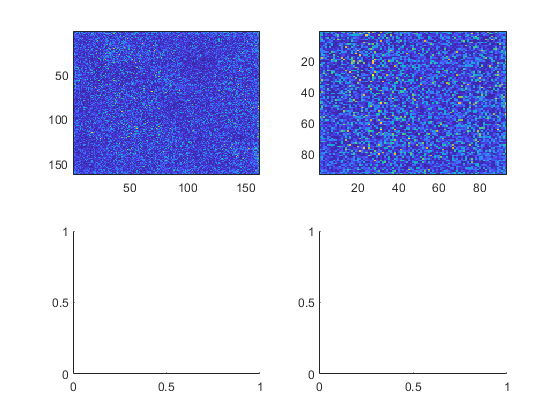

历时 240.884700 秒。


SampleInd = 398

ans = 0.0291

SampleInd = 399

ans = 0.0295

SampleInd = 400

ans = 0.0317

SampleInd = 401

ans = 0.0308

SampleInd = 402

ans = 0.0344

SampleInd = 403

ans = 0.0370

SampleInd = 404

ans = 0.0379

SampleInd = 405

ans = 0.0388

SampleInd = 406

ans = 0.0403

SampleInd = 407

ans = 0.0422

SampleInd = 408

ans = 0.0411

SampleInd = 409

ans = 0.0395

SampleInd = 410

ans = 0.0401

SampleInd = 411

ans = 0.0383

SampleInd = 412

ans = 0.0352

SampleInd = 413

ans = 0.0350

SampleInd = 414

ans = 0.0296

SampleInd = 415

ans = 0.0278

SampleInd = 416

ans = 0.0263

SampleInd = 417

ans = 0.0243

SampleInd = 418

ans = 0.0240

SampleInd = 419

ans = 0.0214

SampleInd = 420

ans = 0.0216

SampleInd = 421

ans = 0.0208

SampleInd = 422

ans = 0.0226

SampleInd = 423

ans = 0.0218

SampleInd = 424

ans = 0.0226

SampleInd = 425

ans = 0.0231

SampleInd = 426

ans = 0.0238

SampleInd = 427

ans = 0.0243

SampleInd = 428

ans = 0.0294

SampleInd = 429

ans = 0.0276

SampleInd = 430

ans = 0.0320

SampleInd = 431

ans = 0.0314

SampleInd = 432

ans = 0.0349

SampleInd = 433

ans = 0.0333

SampleInd = 434

ans = 0.0325

SampleInd = 435

ans = 0.0347

SampleInd = 436

ans = 0.0376

SampleInd = 437

ans = 0.0344

SampleInd = 438

ans = 0.0343

SampleInd = 439

ans = 0.0365

SampleInd = 440

ans = 0.0370

SampleInd = 441

ans = 0.0371

SampleInd = 442

ans = 0.0363

SampleInd = 443

ans = 0.0332

SampleInd = 444

ans = 0.0327

SampleInd = 445

ans = 0.0292

SampleInd = 446

ans = 0.0285

SampleInd = 447

ans = 0.0250

SampleInd = 448

ans = 0.0235

SampleInd = 449

ans = 0.0217

SampleInd = 450

ans = 0.0211

SampleInd = 451

ans = 0.0213

SampleInd = 452

ans = 0.0216

SampleInd = 453

ans = 0.0221

SampleInd = 454

ans = 0.0212

SampleInd = 455

ans = 0.0241

SampleInd = 456

ans = 0.0244

SampleInd = 457

ans = 0.0237

SampleInd = 458

ans = 0.0227

SampleInd = 459

ans = 0.0244

SampleInd = 460

ans = 0.0275

SampleInd = 461

ans = 0.0277

SampleInd = 462

ans = 0.0287

SampleInd = 463

ans = 0.0291

SampleInd = 464

ans = 0.0303

SampleInd = 465

ans = 0.0306

SampleInd = 466

ans = 0.0339

SampleInd = 467

ans = 0.0360

SampleInd = 468

ans = 0.0386

SampleInd = 469

ans = 0.0382

SampleInd = 470

ans = 0.0371

SampleInd = 471

ans = 0.0372

SampleInd = 472

ans = 0.0362

SampleInd = 473

ans = 0.0356

SampleInd = 474

ans = 0.0357

SampleInd = 475

ans = 0.0335

SampleInd = 476

ans = 0.0309

SampleInd = 477

ans = 0.0309

SampleInd = 478

ans = 0.0280

SampleInd = 479

ans = 0.0260

SampleInd = 480

ans = 0.0239

SampleInd = 481

ans = 0.0236

SampleInd = 482

ans = 0.0224

SampleInd = 483

ans = 0.0202

SampleInd = 484

ans = 0.0204

SampleInd = 485

ans = 0.0212

SampleInd = 486

ans = 0.0204

SampleInd = 487

ans = 0.0229

SampleInd = 488

ans = 0.0240

SampleInd = 489

ans = 0.0230

SampleInd = 490

ans = 0.0240

SampleInd = 491

ans = 0.0255

SampleInd = 492

ans = 0.0286

SampleInd = 493

ans = 0.0284

SampleInd = 494

ans = 0.0296

SampleInd = 495

ans = 0.0303

SampleInd = 496

ans = 0.0328

SampleInd = 497

ans = 0.0340

SampleInd = 498

ans = 0.0367

SampleInd = 499

ans = 0.0371

SampleInd = 500

ans = 0.0399

SampleInd = 501

ans = 0.0386

SampleInd = 502

ans = 0.0389

SampleInd = 503

ans = 0.0383

SampleInd = 504

ans = 0.0350

SampleInd = 505

ans = 0.0357

SampleInd = 506

ans = 0.0326

SampleInd = 507

ans = 0.0297

SampleInd = 508

ans = 0.0293

SampleInd = 509

ans = 0.0272

SampleInd = 510

ans = 0.0251

SampleInd = 511

ans = 0.0238

SampleInd = 512

ans = 0.0233

SampleInd = 513

ans = 0.0232

SampleInd = 514

ans = 0.0209

SampleInd = 515

ans = 0.0236

SampleInd = 516

ans = 0.0216

SampleInd = 517

ans = 0.0224

SampleInd = 518

ans = 0.0231

SampleInd = 519

ans = 0.0242

SampleInd = 520

ans = 0.0243

SampleInd = 521

ans = 0.0281

SampleInd = 522

ans = 0.0252

SampleInd = 523

ans = 0.0274

SampleInd = 524

ans = 0.0292

SampleInd = 525

ans = 0.0299

SampleInd = 526

ans = 0.0329

SampleInd = 527

ans = 0.0337

SampleInd = 528

ans = 0.0344

SampleInd = 529

ans = 0.0375

SampleInd = 530

ans = 0.0387

SampleInd = 531

ans = 0.0364

SampleInd = 532

ans = 0.0378

SampleInd = 533

ans = 0.0375

SampleInd = 534

ans = 0.0402

SampleInd = 535

ans = 0.0373

SampleInd = 536

ans = 0.0384

SampleInd = 537

ans = 0.0356

SampleInd = 538

ans = 0.0359

SampleInd = 539

ans = 0.0340

SampleInd = 540

ans = 0.0327

SampleInd = 541

ans = 0.0293

SampleInd = 542

ans = 0.0275

SampleInd = 543

ans = 0.0253

SampleInd = 544

ans = 0.0234

SampleInd = 545

ans = 0.0220

SampleInd = 546

ans = 0.0209

SampleInd = 547

ans = 0.0219

SampleInd = 548

ans = 0.0203

SampleInd = 549

ans = 0.0210

SampleInd = 550

ans = 0.0186

SampleInd = 551

ans = 0.0202

SampleInd = 552

ans = 0.0183

SampleInd = 553

ans = 0.0193

SampleInd = 554

ans = 0.0201

SampleInd = 555

ans = 0.0233

SampleInd = 556

ans = 0.0263

SampleInd = 557

ans = 0.0273

SampleInd = 558

ans = 0.0279

SampleInd = 559

ans = 0.0320

SampleInd = 560

ans = 0.0336

SampleInd = 561

ans = 0.0367

SampleInd = 562

ans = 0.0366

SampleInd = 563

ans = 0.0400

SampleInd = 564

ans = 0.0407

SampleInd = 565

ans = 0.0447

SampleInd = 566

ans = 0.0428

SampleInd = 567

ans = 0.0425

SampleInd = 568

ans = 0.0407

SampleInd = 569

ans = 0.0368

SampleInd = 570

ans = 0.0338

SampleInd = 571

ans = 0.0336

SampleInd = 572

ans = 0.0312

SampleInd = 573

ans = 0.0296

SampleInd = 574

ans = 0.0290

SampleInd = 575

ans = 0.0266

SampleInd = 576

ans = 0.0244

SampleInd = 577

ans = 0.0226

SampleInd = 578

ans = 0.0216

SampleInd = 579

ans = 0.0206

SampleInd = 580

ans = 0.0178

SampleInd = 581

ans = 0.0212

SampleInd = 582

ans = 0.0193

SampleInd = 583

ans = 0.0209

SampleInd = 584

ans = 0.0216

SampleInd = 585

ans = 0.0230

SampleInd = 586

ans = 0.0213

SampleInd = 587

ans = 0.0240

SampleInd = 588

ans = 0.0248

SampleInd = 589

ans = 0.0260

SampleInd = 590

ans = 0.0267

SampleInd = 591

ans = 0.0288

SampleInd = 592

ans = 0.0302

SampleInd = 593

ans = 0.0340

SampleInd = 594

ans = 0.0336

SampleInd = 595

ans = 0.0366

SampleInd = 596

ans = 0.0430

SampleInd = 597

ans = 0.0390

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.21415, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

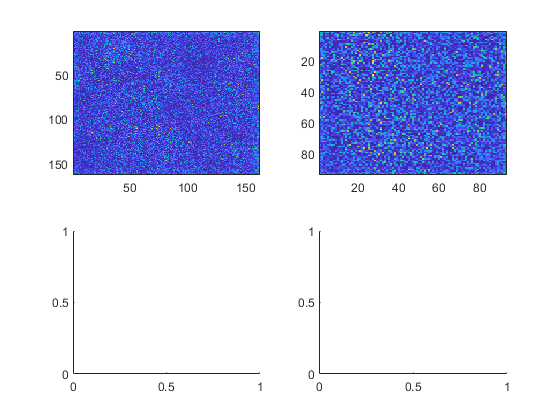

历时 420.008062 秒。


SampleInd = 598

ans = 0.0400

%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.8; N_EEDly = floor(T_EEDly/dt);
% Setup Results Recording

FrE_NW_Drive = zeros(N_E,1);
FrI_NW_Drive = zeros(N_I,1);
mVE_NW_Drive = zeros(N_E,1);
mVI_NW_Drive = zeros(N_I,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Create sliding windows
sampleT = 20;
Sliding = 5;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);

%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(N_E,size(Wins,1)), 'FrIs',   zeros(N_I,size(Wins,1)),...
                 'mVEs',   zeros(N_E,size(Wins,1)), 'mVIs',   zeros(N_I,size(Wins,1)));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE,C_EI,C_IE,C_II,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E_drive,lambda_I_drive,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(mean(lambda_E_drive)) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        WinSize = SimulationT;
        Window = [TimeN*dt-WinSize TimeN*dt];
        
        h = figure('Name','Field_f&V');
        
        subplot 221
        ESPinWin = E_Sp(:,2)>=Window(1) & E_Sp(:,2)<=Window(2);
        E_SpGood = E_Sp(ESPinWin,1);
        [SpCN, SpCI] = groupcounts(E_SpGood);
        FrE_temp = zeros(N_E,1);
        FrE_temp(SpCI) = SpCN*1e3/SimulationT;
        FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC);
        imagesc(FrE_Map)
        
        subplot 222
        ISPinWin = (I_Sp(:,2)>=Window(1) & I_Sp(:,2)<=Window(2));
        I_SpGood = I_Sp(ISPinWin,1);
        [SpCN, SpCI] = groupcounts(I_SpGood);
        FrI_temp = zeros(N_I,1);
        FrI_temp(SpCI) = SpCN*1e3/SimulationT;
        FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);
        imagesc(FrI_Map)
        
        subplot 223
        mVE_temp = zeros(size(mVE_NW_Drive));
        subplot 224
        mVI_temp = zeros(size(mVI_NW_Drive));
        drawnow
        %pause
        close(h)
        toc
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
%         WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
%         T_RateWindow = NWTrace.Wins(SampleInd,:);
%         E_SpInWin = E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) ;
%         I_SpInWin = I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) ;
%         for NeuInd = 1:N_E
%         NWTrace.FrEs(NeuInd,SampleInd) = sum(double(E_Sp(:,1)==NeuInd) & E_SpInWin) *1e3/WinSize;
%         end
%         
%         for NeuInd = 1:N_I
%         NWTrace.FrIs(NeuInd,SampleInd) = sum(double(I_Sp(:,1)==NeuInd) & I_SpInWin) *1e3/WinSize;
%         end
%         NWTrace.mVEs(:,SampleInd) = oVE;
%         NWTrace.mVIs(:,SampleInd) = oVI;
              
        SampleInd = SampleInd + 1
        sum(isnan(oVE))/N_E
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end

toc

历时 420.061234 秒。



NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% % If blown up, discard other recordings...
% if ~BlowUp
%     Fr_NW_BG     = [E_Rate;I_Rate];
%     mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
%     %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
% end
% % end of S_IE loop